# TP3: Réseaux de neurones

Dans ce TP, on s'intéresse à des réseaux de neurones multi-couches complètement connectées (de type perceptron).

# 1. Classification XOR

Dans cet exercice, nous allons entraîner un perceptron à réaliser la fonction "ou exclusif" (ou "XOR"). Pour cela nous utiliserons les outils disponibles dans la toolbox "Deep Learning" de MATLAB.

## 1.1 Jeu de données XOR

La fonction XOR est une fonction de deux variables *booléennes,* qui renvoie VRAI si les deux variables sont distinctes et FAUX sinon. Dans la suite on pose VRAI=1 et FAUX=0.

- Compléter le tableau suivant, donnant les valeurs de sortie de la fonction XOR

                x1 | x2 | y = XOR(x1,x2)

                0  |  0  |  

                0  |  1  |  

                1  |  0  |  

                1  |  1  |  

- Générer un jeu de données labellisées $(X,y) \in \mathbb{R}^{4\times 2} \times \mathbb{R}^4$ correspondant à toutes les entrées possibles de la fonction XOR, et aux sorties associées.

% Insérer votre code ici
X = [0 0; 0 1; 1 0; 1 1]';
y = [0 1 1 0];

## 1.2 Modèle à deux couches

- Utiliser la fonction matlab `feedforwardnet` pour générer un perceptron `nn` à 2 couches et de largeur 2 (i.e. avec deux neurones sur la couche cachée). On consultera l'aide de cette fonction.

% Insérer votre code ici
nn = feedforwardnet(2);

- On donne une représentation graphique de ce réseau ci-dessous:

- Consulter dans la console les propriétés de la première (et unique) couche cachée à l'aide de la commande `nn.layers{1}`. La fonction d'activation pour cette couche est déterminée par l'entrée `nn.layers{1}.transferFcn`. Quelle est ici la fonction d'activation choisie par défaut?

nn.trainParam.goal = 1e-6;
nn.trainParam.mu = 0.001;
nn.divideFcn = 'dividetrain';

- Utiliser la fonction train pour entraîner ce réseau de neurones sur le jeu de données XOR construit précédemment. Quelles sont les nouvelles valeurs des différents poids et biais?

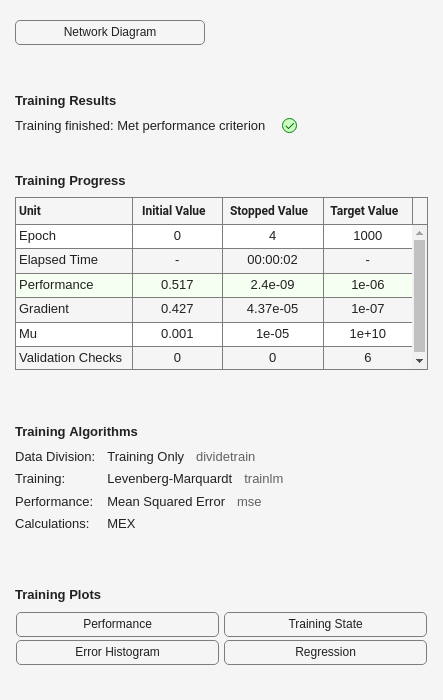

% Insérer votre code ici
nn = train(nn,X,y);

## 1.3 Customisation de l'architecture

Y_pred = nn(X);
Y_pred

Y_pred =     0.0000    1.0000    1.0000   -0.0000


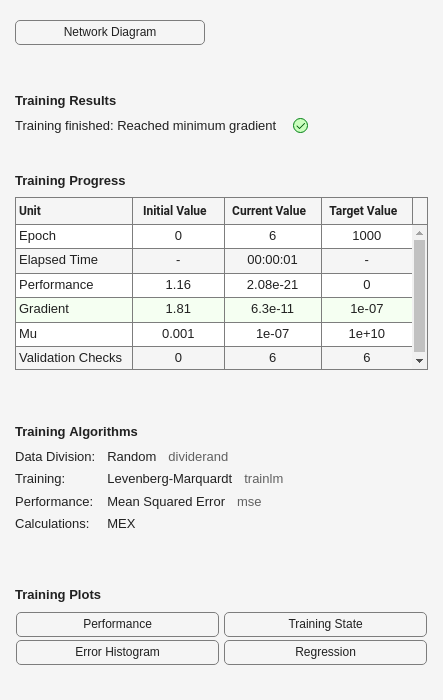


nn1 = feedforwardnet(3);
nn1.layers{1}.transferFcn = 'poslin';
nn1 = train(nn1,X,y);
Y1 = nn1(X); Y1 = (Y1-min(Y1))./(max(Y1)-min(Y1));

nn2 = feedforwardnet([3,2]);
nn2 = train(nn2,X,y);
Y2 = nn2(X); Y2 = (Y2-min(Y2))./(max(Y2)-min(Y2));

nn3 = feedforwardnet([4,3,2]);
nn3 = train(nn3,X,y);

Y3 = nn3(X); Y3 = (Y3-min(Y3))./(max(Y3)-min(Y3));

- Créer et entraîner comme précédemment les architectures suivantes

- -

# 2. Classification multi-labels (données synthétiques)

Dans cette partie, on s'intéresse à des réseaux de neurones multi-couches complètement connectées. Le but est de vous faire implémenter vous-même une descente de gradient pour entraîner le réseau, en utilisant la rétro-propagation. 

Voici quelques fonctions qui vous seront utiles dans ce tp. En MATLAB, les fonctions anonymes sont une façon pratique de déclarer des fonctions simples sans avoir à les sauvegarder dans un fichier séparé.

dotp = @(x,y) sum(x(:)'*y(:)); % produit scalaire

# 3. Classification données réelles